# Slab Waveguide - Calculations

## Introduction

This script solves for the modes of the slab waveguide, calculates the effective indices, and plot the corresponding E-field profile for all the modes. This will help you gain an understanding of waveguide behavior and the principles of light propagation in optical devices.

## Task

Use the interactive controls to modify the following parameters:

- thickness of the silicon layer

- desired polarization to plot

Observe the corresponding affects on effective indices and electric field profile for both TE and Transverse Magnetic (TM) polarizations. 

Change the thickness from 220 nm. You may also choose to view the field profile for the TM polarization.

thickness=220;   %%% thickness of the silicon layer, [units: nm]
polarization = 'TE';          %%% polarization, 'TE' or 'TM'

[x, TE_E, TE_H, TM_E, TM_H, nTE, nTM] = wg_1D_mode_profile ...
    (1.55e-6, thickness, 1.444, 3.47, 1.444, 100, 3);

Effective index value(s) of the TE mode(s)

nTE

nTE = 2.8418

Effective index value(s) of the TM mode(s)

nTM

nTM = 2.0489

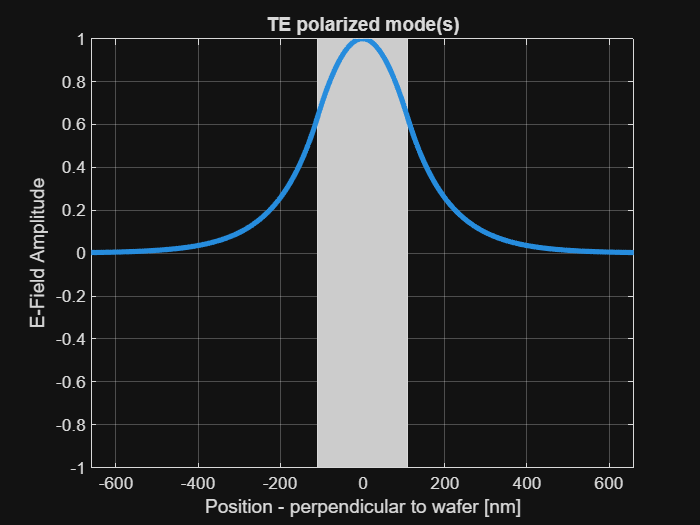

figure;
g=rectangle('Position',[-thickness/2,-1,thickness,2],'FaceColor',[.8 .8 .8]); hold all;
switch polarization
    case 'TE'
        plot(x*1e9, TE_E/max(max(TE_E)), 'LineWidth',3);
    case 'TM'
        plot(x*1e9, TM_E/max(max(TM_E)), 'LineWidth',3);
end
title([polarization ' polarized mode(s)']);

xlabel('Position - perpendicular to wafer [nm]');
ylabel('E-Field Amplitude');
axis tight;
grid on; box on;

% Helper Functions

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% wg_1D_mode_profile.m - Calculate the 1D mode profile of a slab waveguide
% by Lukas Chrostowski, 2012
% See Yariv Photonics book, Chapter 3.2
% - function returns mode profiles for TE and TM modes (E, H components)
% usage, e.g.:
%  [x, TE_E, TE_H, TM_E, TM_H, nTE, nTM] = wg_1D_mode_profile (1.55e-6, 0.22e-6, 1.444, 3.47, 1.444, 100, 4)
%  plot (x, TE_E);
%  plot (x, TM_E);

function [x, TE_E, TE_H, TM_E, TM_H, nTE, nTM]= wg_1D_mode_profile (lambda, t, n1, n2, n3, pts, M)
t = t*1e-9; % convert t from nm to meters
[nTE,nTM,TEparam,TMparam]= wg_1D_analytic(lambda,t,n1,n2,n3);
x1=linspace( -M*t, -t/2, pts); x2=linspace( -t/2, t/2, pts);
x3=linspace( t/2, M*t, pts); x=[x1 x2 x3];
nx=[n1*ones(pts,1); n2*ones(pts,1); n3*ones(pts,1)]';
mu0=4*pi*1e-7; epsilon0=8.85e-12; eta=sqrt(mu0/epsilon0); c=3e8; % constants
for i=1:length(nTE)
    h=TEparam(i,2);q=TEparam(i,3); p=TEparam(i,4);
    beta = 2*pi*nTE(i)/lambda;
    C=2*h*sqrt ( 2*pi*c/lambda*mu0 / (beta * (t+1/q+1/p)*(h^2+q^2) ) ); % normalize to 1W
    % n1, n2, n3 regions
    TE_E(i,:)=C*[exp(q*(x1+t/2)), (cos(h*(x2+t/2))+q/h*sin(h*(x2+t/2))), (cos(h*t)+q/h*sin(h*t)).*exp(-p*(x3-t/2))];
end
TE_H=TE_E'.*(nx'*ones(1,length(nTE)))/eta;

for i=1:length(nTM)
    h=TMparam(i,2); q=TMparam(i,3);
    p=TMparam(i,4); qb=n2^2/n1^2*q;pb=n2^2/n3^2*p;
    beta = 2*pi*nTM(i)/lambda;
    temp=(qb^2+h^2)/qb^2 * (t/n2^2 + (q^2+h^2)/(qb^2+h^2)/n1^2/q + ( p^2+h^2)/(p^2+h^2)/n3^2/p) ;
    C=2*sqrt ( 2*pi*c/lambda*epsilon0 / (beta * temp )); % normalize to 1W
    TM_H(i,:)=C*[h/qb*exp(q*(x1+t/2)), (h/qb*cos(h*(x2+t/2))+sin(h*(x2+t/2))), (h/qb*cos(h*t)+sin(h*t)).*exp(-p*(x3-t/2))];
end
TM_E=TM_H'./(nx'*ones(1,length(nTM)))*eta;
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% wg_1D_analytic.m - Analytic solution of a slab waveguide
% by Lumerical Solutions, http://www.lumerical.com/mode_online_help/slab_wg.m
% modified by Lukas Chrostowski, 2012
% See Yariv Photonics book, Chapter 3
% finds the TE and TM effective indices of a 3-layer slab waveguide

% usage:
%  - get effective indices for supported modes:
%  [nTE, nTM] = wg_1D_analytic (1.55e-6, 0.22e-6, 1.444, 3.47, 1.444)
%  - optional, for plotting: TEparam,TMparam: h, q, p parameters of the mode.

function [nTE,nTM,TEparam,TMparam]=wg_1D_analytic (lambda, t, n1, n2, n3)
k0 = 2*pi/lambda;
b0 = linspace( max([n1 n3])*k0, n2*k0, 1000);   %k0*n3 less than b less than k0*n2
b0 = b0(1:end-1);
te0=TE_eq(b0,k0,n1,n2,n3,t);
tm0=TM_eq(b0,k0,n1,n2,n3,t);

%TE
intervals=ge(te0,0)-lt(te0,0);
izeros=find(lt(diff(intervals),0));
X0=[b0(izeros); b0(izeros+1)]';
[nzeros,scrap]=size(X0);
for i=1:nzeros
    nTE(i)=fzero(@(x) TE_eq(x,k0,n1,n2,n3,t),X0(i,:))/k0;
    [TEparam(i,1),TEparam(i,2),TEparam(i,3),TEparam(i,4)]= TE_eq(nTE(i)*k0,k0,n1,n2,n3,t);
end
nTE=nTE(end:-1:1);
TEparam=TEparam(end:-1:1,:);

%TM
intervals=ge(tm0,0)-lt(tm0,0);
izeros=find(lt(diff(intervals),0));
X0=[b0(izeros); b0(izeros+1)]';
[nzeros,scrap]=size(X0);
for i=1:nzeros
    nTM(i)=fzero(@(x) TM_eq(x,k0,n1,n2,n3,t),X0(i,:))/k0;
    [TMparam(i,1),TMparam(i,2),TMparam(i,3),TMparam(i,4)]= TM_eq(nTM(i)*k0,k0,n1,n2,n3,t);
end
if gt(nzeros,0)
    nTM=nTM(end:-1:1);
    TMparam=TMparam(end:-1:1,:);
else
    nTM=[];
end
end

function [te0,h0,q0,p0]=TE_eq(b0,k0,n1,n2,n3,t)
h0 = sqrt( (n2*k0)^2 - b0.^2 );
q0 = sqrt( b0.^2 - (n1*k0)^2 );
p0 = sqrt( b0.^2 - (n3*k0)^2 );
% the objective is to find zeroes of te0 and tm0
te0 = tan( h0*t ) - (p0+q0)./h0./(1-p0.*q0./h0.^2);
end

function [tm0,h0,q0,p0]=TM_eq(b0,k0,n1,n2,n3,t)
h0 = sqrt( (n2*k0)^2 - b0.^2 );
q0 = sqrt( b0.^2 - (n1*k0)^2 );
p0 = sqrt( b0.^2 - (n3*k0)^2 );
pbar0 = (n2/n3)^2*p0;
qbar0 = (n2/n1)^2*q0;
tm0 = tan( h0*t ) - h0.*(pbar0+qbar0)./(h0.^2-pbar0.*qbar0);
end